# Supplementary Figure 6 on events

The correlation between task performance and decoding accuracy.

org = Org;
org.init;

p = Pub(20, 5, 'rows', 1, 'columns', 3);
p.panel(1, 'xlab', 'Trials per session', 'ylab', 'Performance per session');
org.correlogram('num_trials', 'performance', false, true);

Using only 73 out of 110 sessions
Sessionwise correlations num_trials vs. performance: adj. R^2 = 0.707
Pearson: 0.843, p = 7.924487e-21, ***
Spearman: 0.909, p = 9.129319e-29, ***
Kendall: 0.747, p = 1.009995e-20, ***


p.panel(2, 'xlab', 'Trials per session', 'ylab', 'log_{10}(I_0N)');
org.correlogram('num_trials', 'log_I0N', false, true);

Using only 73 out of 110 sessions
Sessionwise correlations num_trials vs. log_I0N: adj. R^2 = 0.150
Pearson: 0.402, p = 4.176909e-04, ***
Spearman: 0.473, p = 2.356191e-05, ***
Kendall: 0.346, p = 1.561947e-05, ***


p.panel(3, 'xlab', 'Task performance', 'ylab', 'log_{10}(I_0N)');
org.correlogram('performance', 'log_I0N', false, true);

Using only 73 out of 110 sessions
Sessionwise correlations performance vs. log_I0N: adj. R^2 = 0.302
Pearson: 0.559, p = 2.799665e-07, ***
Spearman: 0.598, p = 2.287066e-08, ***
Kendall: 0.427, p = 9.121795e-08, ***


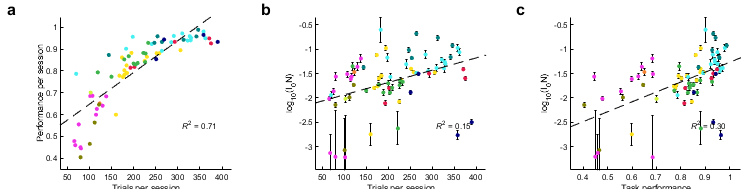

p.format;
Utils.printto('events_figs/f2_supplements', 'performance_vs_decoding.pdf');

Path analysis between the number of trials, the task performance (# correct trials [achieved reward] / # total attempted trials), and the log of I0N per session:

f = SessManager.highqual_filt_from_usable;
nt = zscore(org.sess_prop.num_trials(f));
pf = zscore(org.sess_prop.performance(f));
li = zscore(org.sess_prop.log_I0N(f));

tab = array2table([nt pf li], 'VariableNames', {'num_trials', 'performance', 'logI0N'});

fitlm(tab, 'performance ~ num_trials')

ans = Linear regression model:
    performance ~ 1 + num_trials

Estimated Coefficients:
                    Estimate         SE         tStat         pValue  
                   ___________    ________    __________    __________

    (Intercept)    -6.1834e-16    0.063342    -9.762e-15             1
    num_trials         0.84331    0.063781        13.222    7.9245e-21


Number of observations: 73, Error degrees of freedom: 71
Root Mean Squared Error: 0.541
R-squared: 0.711,  Adjusted R-Squared: 0.707
F-statistic vs. constant model: 175, p-value = 7.92e-21

fitlm(tab, 'logI0N ~ num_trials + performance')

ans = Linear regression model:
    logI0N ~ 1 + num_trials + performance

Estimated Coefficients:
                    Estimate       SE         tStat         pValue  
                   __________    _______    __________    __________

    (Intercept)    1.0514e-15    0.09727    1.0809e-14             1
    num_trials       -0.23819    0.18224        -1.307       0.19549
    performance       0.75955    0.18224        4.1677    8.6642e-05


Number of observations: 73, Error degrees of freedom: 70
Root Mean Squared Error: 0.831
R-squared: 0.329,  Adjusted R-Squared: 0.309
F-statistic vs. constant model: 17.1, p-value = 8.84e-07